# Metadata Classification

Import metadata + classifications

clc; clear;
metaDataCell = readtable("ISIC_2019_Training_Metadata.csv")

metaDataCell = 25331×5 table
         image          age_approx    anatom_site_general    lesion_id       sex    
    ________________    __________    ___________________    _________    __________

    {'ISIC_0000000'}        55        {'anterior torso' }       NaN       {'female'}
    {'ISIC_0000001'}        30        {'anterior torso' }       NaN       {'female'}
    {'ISIC_0000002'}        60        {'upper extremity'}       NaN       {'female'}
    {'ISIC_0000003'}        30        {'upper extremity'}       NaN       {'male'  }
    {'ISIC_0000004'}        80        {'posterior torso'}       NaN       {'male'  }
    {'ISIC_0000006'}        25        {'posterior torso'}       NaN       {'female'}
    {'ISIC_0000007'}        25        {'posterior torso'}       NaN       {'female'}
    {'ISIC_0000008'}        30     

classificationsCell = readtable("groundtruth_categorical.csv")

classificationsCell = 25331×2 table
         image                category       
    ________________    _____________________

    {'ISIC_0000000'}    {'Melanocytic nevus'}
    {'ISIC_0000001'}    {'Melanocytic nevus'}
    {'ISIC_0000002'}    {'Melanoma'         }
    {'ISIC_0000003'}    {'Melanocytic nevus'}
    {'ISIC_0000004'}    {'Melanoma'         }
    {'ISIC_0000006'}    {'Melanocytic nevus'}
    {'ISIC_0000007'}    {'Melanocytic nevus'}
    {'ISIC_0000008'}    {'Melanocytic nevus'}
    {'ISIC_0000009'}    {'Melanocytic nevus'}
    {'ISIC_0000010'}    {'Melanocytic nevus'}
    {'ISIC_0000011'}    {'Melanocytic nevus'}
    {'ISIC_0000012'}    {'Melanocytic nevus'}
    {'ISIC_0000013'}    {'Melanoma'         }
    {'ISIC_0000014'}    {'Melanocytic nevus'}
    {'ISIC_0000015'}    {'Melanocytic nevus'}
    {'ISIC_0000016'}    {'Melanocytic nevus'}


binary_classificationCell = readtable("ISIC_2019_Training_GroundTruth.csv");
labels = unique(classificationsCell.category);


Construct feature matrix

X1 = metaDataCell.age_approx;
X2 = categorical(metaDataCell.anatom_site_general);
X2 =grp2idx(X2);
X3 = categorical(metaDataCell.sex);
X3 =grp2idx(X3);
X = [X1 X2 X3];

Construct the "Y" classification matrix

Y = categorical(classificationsCell.category);

Split into training set and test set

Use mnrfit to conduct multi-nominal regression

[B,dev,stats] = mnrfit(X,Y);%three variables, B is a coefficient from
yval = mnrval(B,X);

Display B the log coefficient predictors of each feature

T = table(B(:,1),B(:,2),B(:,3),B(:,4),B(:,5),B(:,6),B(:,7))

T = 4×7 table
      Var1         Var2         Var3          Var4         Var5         Var6        Var7  
    _________    _________    _________    __________    _________    ________    ________

      -1.6816     -0.43019     -0.11517      -0.29811       4.9856     0.99498     -4.9469
      0.05823     0.050586     0.040487    -0.0083611    -0.034624    0.027515    0.077893
     -0.14913    -0.095126    -0.022711       0.14777     0.085675    0.047858    0.054679
    -0.041365      0.24595      0.10935       0.15201      0.18956     0.15508     0.54969


B = exp(B);
T = table(B(:,1),B(:,2),B(:,3),B(:,4),B(:,5),B(:,6),B(:,7))

T = 4×7 table
     Var1       Var2       Var3       Var4       Var5       Var6       Var7   
    _______    _______    _______    _______    _______    ______    _________

    0.18607    0.65039    0.89121    0.74222     146.29    2.7047    0.0071058
       1.06     1.0519     1.0413    0.99167    0.96597    1.0279        1.081
    0.86146    0.90926    0.97754     1.1592     1.0895     1.049       1.0562
    0.95948     1.2788     1.1155     1.1642     1.2087    1.1678       1.7327


stats.p %why do some show 0? doesn't this mean null hypothesis is completely rejected?

ans =     0.0000    0.1770    0.7202    0.4796    0.0000    0.0014    0.0000
    0.0000    0.0000    0.0000    0.1556    0.0000    0.0000    0.0000
    0.0000    0.0007    0.4234    0.0000    0.0017    0.0837    0.0799
    0.7873    0.0812    0.4429    0.4220    0.1680    0.2661    0.0007


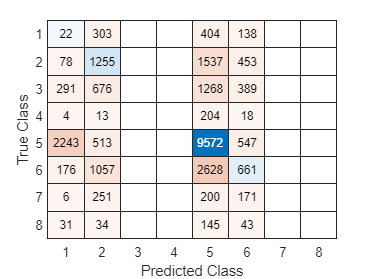

%potentially overfitting problem
[val, idx] = max(yval, [], 2);
Y = double(Y);
confusionchart(Y,idx)

Visualize Data with a 3D plot

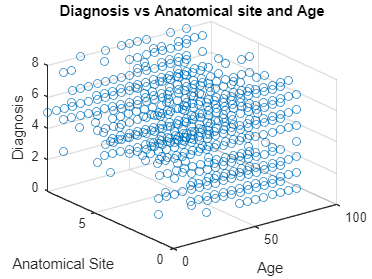

scatter3(X1,X2,Y)
title("Diagnosis vs Anatomical site and Age")
xlabel("Age")
ylabel("Anatomical Site")
zlabel("Diagnosis")

table(labels)

ans = 8×1 table
              labels           
    ___________________________

    {'Actinic keratosis'      }
    {'Basal cell carcinoma'   }
    {'Benign keratosis'       }
    {'Dermatofibroma'         }
    {'Melanocytic nevus'      }
    {'Melanoma'               }
    {'Squamous cell carcinoma'}
    {'Vascular lesion'        }


AnatomicalSites = unique(metaDataCell.anatom_site_general);
AnatomicalSites(1) = [];
table(AnatomicalSites)

ans = 8×1 table
      AnatomicalSites  
    ___________________

    {'anterior torso' }
    {'head/neck'      }
    {'lateral torso'  }
    {'lower extremity'}
    {'oral/genital'   }
    {'palms/soles'    }
    {'posterior torso'}
    {'upper extremity'}
